This code will simulate a time course in the target area using a specified ground-truth CF model. The different models under consideration are:

- a single gaussian (SG)

- a difference of gaussians (DoG)

For each of the two simulated relations between source region and target voxel, both models will be fitted using the MCMC code. To this end the MCMC_CF_cluster.m code has been slightly modified and saved under MCMC_CF_cluster_Model.m. Furthermore, the file compute_mcmc_predictions.m has been modified to allow a selection of the model that needs to be fitted. Finally, the file variables_definition.m has been modified. It now includes a function for BIC and a function for AIC calculations. In this simulation, the "true" signal in the target region is generated from the fMRI signal obtained from the source region of an actual participant (subj1 in the example data). It is further of note that for current purposes, the DoG model has been simplified to have only two free parameters (center location and spread of the positive Gaussian; the spread of the second negative Gaussian is fixed at 10 times the spread of the first).

clear all

## Define constants

variables_definition; %load the other variables

SigmaNoiseTarget = 0.1; % Add a little noise to the target time series; no need to do this for the source region (real data).
MyLSigma=-0.05; %The latent parameter used to calculate sigma. 
Gain=1;% A parameter to potentially change the "gain" between the source and the target. For this demonstration not used.
how_beta=1; % 0 for bCF option A (i.e. estimate beta using OLS) and 1 for bCF option B (i.e. estimate a posterior for beta).

TrueModeloption = "Gauss";
TrueModelWidth = 5;
TrueCenter = 250;

## **Define inline functions and models**

switch lower(TrueModeloption)
    case "gauss"
        M=@(d)(exp((-d.^2)/(2*TrueModelWidth.^2)));
    case "dog"
        M=@(d)(exp((-d.^2)/(2*TrueModelWidth.^2))...
          -0.3*exp((-d.^2)/(10*TrueModelWidth.^2)));
otherwise
        error('wrong model selected')
end

## Build target signal using known model parameters and real data

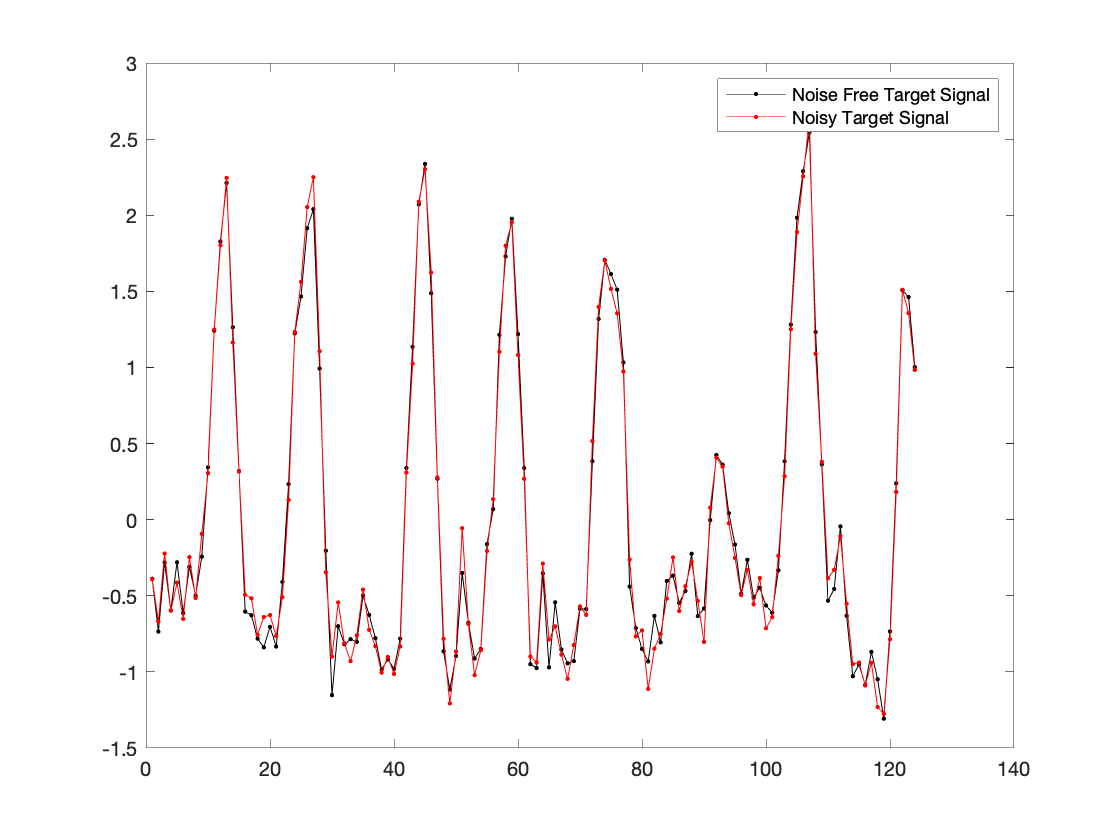

load('tSeries_sub1.mat');
T = tSeries_data.tSeries_source * M(tSeries_data.D(:,TrueCenter)) .* Gain;
Ttotal = zscore(T) + SigmaNoiseTarget*randn(size(T));
Ttotal = zscore(Ttotal);
figure; plot(zscore(T),'k.-'); hold on; plot(Ttotal,'r.-'); hold off;
legend({'Noise Free Target Signal','Noisy Target Signal'});

## Fit target data with single Gaussian model (two parameters)

tSeries_data_syn_Gauss=tSeries_data; %initialize the structure
tSeries_data_syn_Gauss.idxTarget=tSeries_data.idxTarget(333);
tSeries_data_syn_Gauss.tSeries_target=Ttotal;
tSeries_data_syn_Gauss.Model='gauss';
[Syn_bayes_CF_Gauss] = MCMC_CF_cluster_Models(tSeries_data_syn_Gauss);


## Fit target data with simplified DoG model (also two parameters, because sigma2 == 10*sigma1)

tSeries_data_syn_DoG=tSeries_data; %initialize the structure
tSeries_data_syn_DoG.idxTarget=tSeries_data.idxTarget(333);
tSeries_data_syn_DoG.tSeries_target=Ttotal;
tSeries_data_syn_DoG.Model='dog';
[Syn_bayes_CF_DoG] = MCMC_CF_cluster_Models(tSeries_data_syn_DoG);

## Plot Model Likelihood 

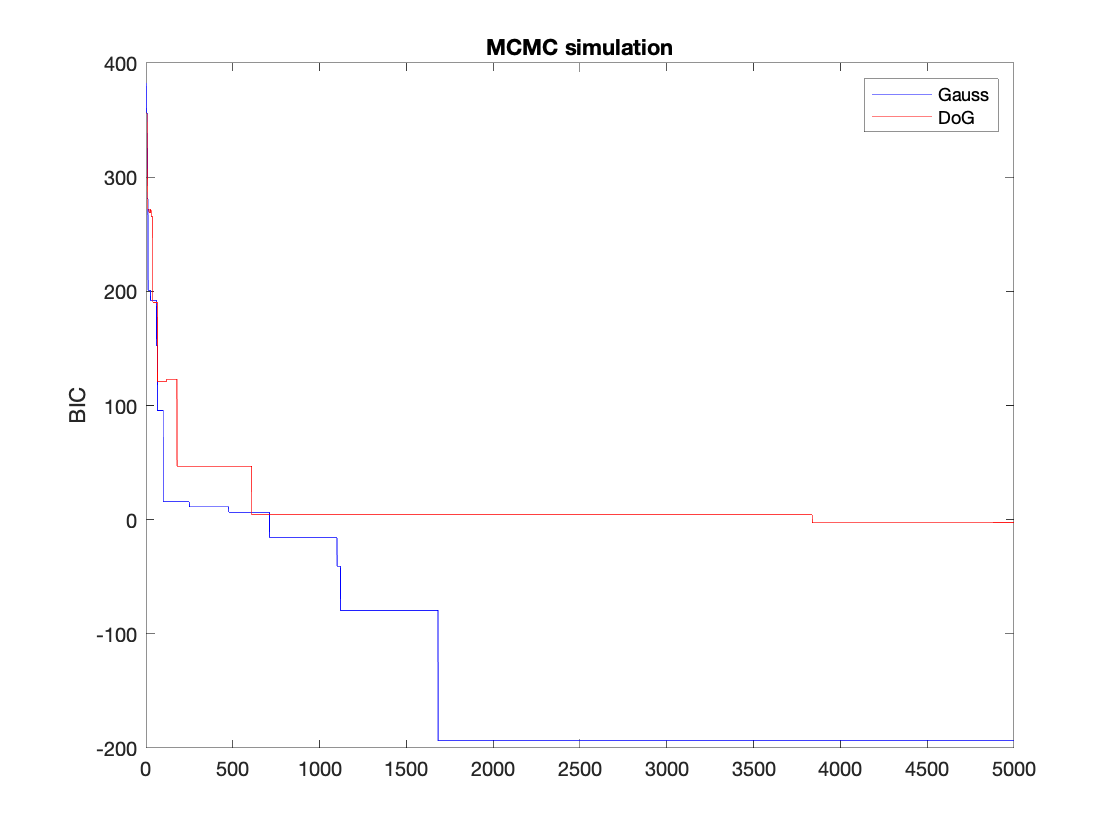

plot([Syn_bayes_CF_Gauss(:).BICAIC.BIC],'b'); hold on;
plot([Syn_bayes_CF_DoG(:).BICAIC.BIC],'r'); hold off;
legend({'Gauss','DoG'}); title('MCMC simulation'); ylabel('BIC'); 

## Show best fitting predictions

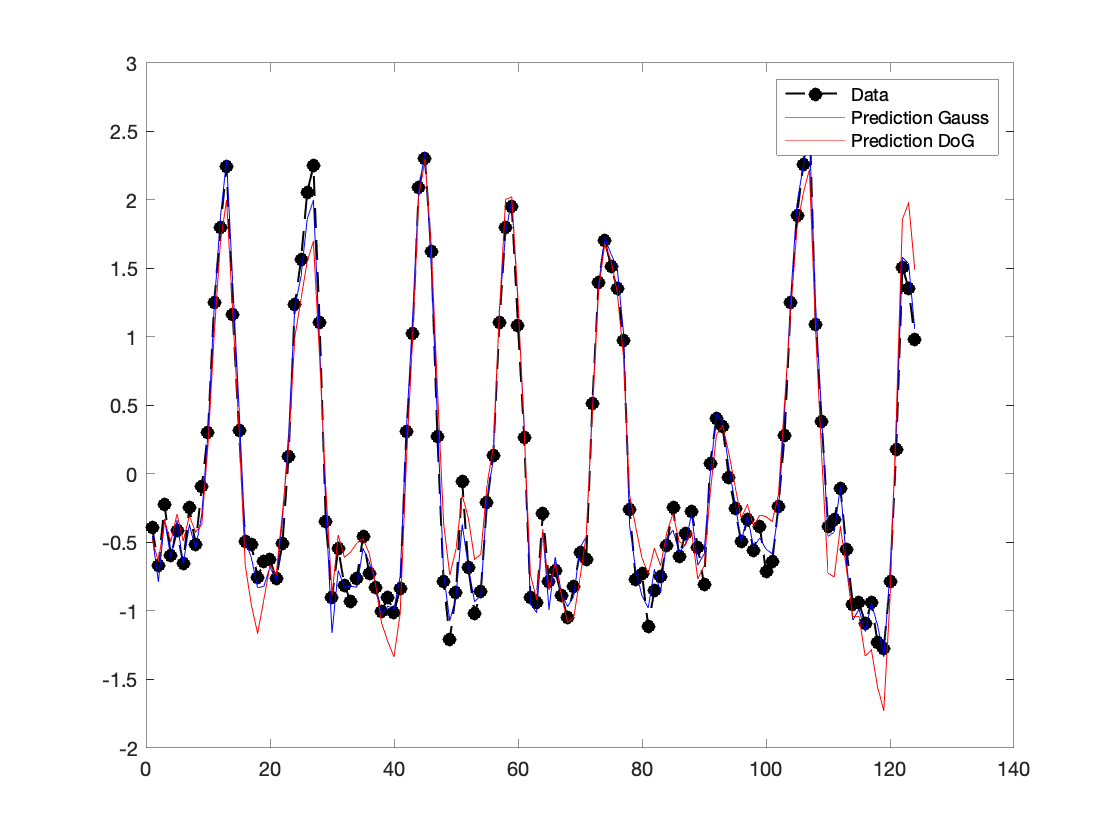

figure; title('Best-fitting Model Predictions')
plot(Ttotal,'ko--','markerfacecolor','k','linewidth',1); hold on; 

weight = @(d,sigma) exp((-d.^2)/(2*sigma.^2));
w = weight(tSeries_data.D(:,Syn_bayes_CF_Gauss.best_fit(3)),Syn_bayes_CF_Gauss.best_fit(1));
Pgauss = tSeries_data.tSeries_source * w * Syn_bayes_CF_Gauss.best_fit(2);
plot(Pgauss,'b'); 

weight = @(d,sigma) exp((-d.^2)/(2*sigma.^2))-0.3*exp((-d.^2)/(10*sigma.^2));
w = weight(tSeries_data.D(:,Syn_bayes_CF_DoG.best_fit(3)),Syn_bayes_CF_DoG.best_fit(1));
Pdog = tSeries_data.tSeries_source * w * Syn_bayes_CF_DoG.best_fit(2);
plot(Pdog,'r'); legend({'Data','Prediction Gauss','Prediction DoG'});


fprintf(1,'The true CF was a %s [M = %s]',TrueModeloption,func2str(M));

The true CF was a Gauss [M = @(d)(exp((-d.^2)/(2*TrueModelWidth.^2)))]

RSS = sum((Ttotal-Pgauss).^2); SST = sum((Ttotal).^2);
Rsq = 1 - (RSS / SST); fprintf(1,'Variance Explained by Gaussian Model: %1.5f [BIC = %1.3f]',Rsq,Syn_bayes_CF_Gauss.best_fit(5));

Variance Explained by Gaussian Model: 0.98854 [BIC = -199.296]

RSS = sum((Ttotal-Pdog).^2); SST = sum((Ttotal).^2);
Rsq = 1 - (RSS / SST); fprintf(1,'Variance Explained by DoG Model: %1.2f [BIC = %1.3f]',Rsq,Syn_bayes_CF_DoG.best_fit(5));

Variance Explained by DoG Model: 0.95 [BIC = -8.496]